Water Jacket

Non End

##  [TC]  변수 구조화

- 변수 - 구분기준 -  1)jmag내, matlab내 변수 2) 파트 3) 변수종류(열저항, 열용량, Dimension) -> Filtering활용

- 수식 (equation)

- (measurement)

1. End

1)Circuit 에서 Coil End Component로 구사

2)3D Model에서 구현후 R로 구현 (JCR) - Motorcad 참조 

2. Cooling

1)JCF는 유사

2)JCR에 따라 Oil Spray & Water Cooling 구분 

## Input Variable and calcThermalSubVariable

scaleFactor =           1
tempThermalInputVariableThermal3DOuterRotorWindPjt
% tempThermalInputVariable
calcThermalSubVariable
%  createJmagGeomSet(geomApp)
%  getEdgeItemFromString(testString)
% mk
%  mkfaceSetListTable()
%  mkEdgeItem

## 1.  Modelling

### 0. 2D 모델링 정보 가져오기

if contains(MachineData.runnerType,'outer','IgnoreCase',true)
    Circuit2LoadPath="Z:/Simulation/WindProject/ThermalCircuitFromJFT160.jcir";
else
    Circuit2LoadPath="Z:\Thesis\00_Theory_Prof\01_Thermal\JFT160ThermalParametric\baseCircuitParametric.jcir";
end
% 2D -> 3D outter Rotor
devJmagSettingV3 
app(2) = actxserver(strcat('Designer.Application.','222'));

NumModels=app.NumModels

% Model.RestoreCadLink(0)

for ModelIndex=1:NumModels
    ModelObj{ModelIndex}=app.GetModel(ModelIndex-1)
    ModelObj{ModelIndex}.GetName
end

%
Model3d=app.GetModel(0)
Model3d.IsValid
Model3d.GetName
Model3d.RestoreCadLink(0)

geomApp=app.CreateGeometryEditor(0);
geomApp.Show

NumCurModelStudies=Model3d.NumStudies


### 1. RegionTable Part 종류별로 분류

% RegionTablePerType < [otherSlotAreaGeomTable,StatorAssemRegionTable,RegionTablePerType]=findnReNameOtherSlotArea(StatorAssemRegionTable)
% RotorRegionTablePerType = detRotorRegionTablePerType(RotorAssemRegionTable)

RotorRegionTablePerType = detRotorRegionTablePerType(RotorAssemRegionTable)

### 2. 2D->3D

ExtrudeLength=MachineData.StatorLength/3   % MachineData From devJmagSettingV2
Model3d=app.GetCurrentModel
Model3d.IsValid
Model3d.ExtendTo3DSolid(ExtrudeLength, true)
Model3d.UpdateCadModel(true)
% Model.ClearMeshGroupSettingAllStudies()
% Model.RestoreCadLink(0)
setGeomExtrudeType(1,'Stator',geomApp)
setGeomExtrudeType(1,'Rotor',geomApp)

%mkSolidIdentifierName
%mkSubIdName4RegionExtrude

### 3. Copy Stator Sketch Part종류 개수만큼 일단 7개  & Get Part Name List

% for RotorRegionIndex=1:height(RotorAssemRegionTable)
% end
% GetMeasureManager.MeasureDistance(RotorGeomArcTable.StartVertexTableItemobj(1),RotorGeomLineTable.StartVertexTableItemobj(2))


%% Copy and Paste Sketch

% Stator
StatorNameStruct=copyGeomPartFromTable(StatorAssemRegionTable,geomApp)
% Rotor
RotorNameStruct =copyGeomPartFromTable(RotorAssemRegionTable,geomApp)


#### [TC]이름을 제외한 Region은 삭제하기

removeRegionExceptPartName(StatorNameStruct,StatorRegionTablePerType,geomApp)
removeRegionExceptPartName(RotorNameStruct,RotorRegionTablePerType,geomApp)


### 3. 3D AssemDataTable

#### 1) get AssemTable

% getGeomAssemItemListTable
AssemTable=getGeomAssemItemListTable(geomApp)
%[TD] AssembleAllPartName=getGeomPartlistCell(geomApp);

geomApp.Hide

#### 2) add AssemPartDataTable

% getSGeomPartData
% AssemPartStruct=struct();
for AssemItemIndex=1:height(AssemTable)
    if ~contains(AssemTable.AssemItemName{AssemItemIndex},'Plane')
    AssemTable.AssemPartTable{AssemItemIndex}=getSGeomPartData(geomApp,AssemTable.AssemItemName{AssemItemIndex})
    end
end




geomApp.Show
% 
% % Sketch ->Part 
% ref1 = geomApp.GetDocument().GetAssembly().GetItem("Stator").GetItem("Stator")
% geomApp.GetDocument().GetAssembly().GetItem("Stator").CreateExtrudeSolid(ref1)
% geomApp.GetDocument().GetAssembly().GetItem("Stator").GetItem("Stator").SetProperty("Visible", 0)
% 
% doublearray = [0 for i in range(1)]
% doublearray[0] = 1
% geomApp.GetDocument().GetAssembly().GetItem("Stator").GetItem("Extrude").SetProperty("SpecifiedRatio", doublearray)
% geomApp.GetDocument().GetAssembly().GetItem("Stator").GetItem("Extrude").SetProperty("Type", 1)
% geomApp.GetDocument().GetAssembly().GetItem("Stator").GetItem("Extrude").SetProperty("Height", "Height/3")

#### 3) Face Extrude

% [TB]devCreateGeomFaceExtrudeSolid
%devCreateGeomFaceExtrudeSolid(doublearray,PartName,geomApp)
for AssemItemIndex=1:height(AssemTable)
    PartName=AssemTable.AssemItemName{AssemItemIndex}
    BoolfaceExtrude=contains(AssemTable.AssemPartTable{AssemItemIndex}.IdentifierName,'face(TExtrudeSolid')
    BoolNonEdge=~contains(AssemTable.AssemPartTable{AssemItemIndex}.IdentifierName,'edge')
    BoolNonLump=~contains(AssemTable.AssemPartTable{AssemItemIndex}.IdentifierName,'lump')
    IndexList4FaceExtrude=and(and(BoolfaceExtrude,BoolNonEdge),BoolNonLump)    
    List4FaceExtrude=AssemTable.AssemPartTable{AssemItemIndex}.IdentifierName(IndexList4FaceExtrude)    
    devCreateGeomFaceExtrudeSolid(List4FaceExtrude,PartName,geomApp)
end

3. AssemPartList

%  Get Geom Assem Part Data
AssemPartStruct=getAssemPartListStruct(geomApp);
% 선택 구조 짜기

% AssemItem                          AssemItemName     AssemPartTable    GeomSetList    GeomSetTable


### 4. Create Geom Set

####     1) [TC]Geom Set List 2 AssemTable

    %  [TC] mkGeomSetListTable() % TBC Outer Rotor Case
    % [TC] 
    for AssemTableIndex=1:height(AssemTable)
        PartName=AssemTable.AssemItemName{AssemTableIndex}
        GeomSetListTable=mkGeomSetListTable(PartName,runnerType)
        AssemTable.GeomSetList{AssemTableIndex}=GeomSetListTable;
    end

% add Coil-End Set 
% add Coil-Stator Face    
%  getEdgeItemFromString(testString)
% mk
%  mkEdgeItem

####     2) [TC] CreateJmagGeomSet

% [TC] createJmagGeomSet(geomApp)

% AssemTable=addGeomSetList2AssemTable(AssemTable,geomApp)
for AssemTableIndex=1:height(AssemTable)

    newGeomSetTable=createJmagGeomSet(AssemTable.GeomSetList{AssemTableIndex},geomApp)
    AssemTable.GeomSetTable{AssemTableIndex}=newGeomSetTable;
end
geomApp.Show
newGeomSetTable
%% Manual
% Coil and Core Contact Patter



4.5 addMaterial

Steady2=app.GetModel(1).GetStudy(0)
addJmagMaterialByName("coil material",Steady2)
addJmagMaterialByName("core material",Steady2)
addJmagMaterialByName("magnet material",Steady2)

### 5. Turn Into Full Model 

% find(contains(AssemPartStruct(1).AssemPartTable.IdentifierName,subIdentifierName))
% find(strcmp(AssemPartStruct(1).AssemPartTable.IdentifierName,subIdentifierName))
% 
% IdentifierName=AssemPartStruct(1).AssemPartTable.IdentifierName{1}
% % mkSubIdName4RegionExtrude
% % mkSolidIdentifierName
% splitedIdNameCell=splitGeomIdName(IdentifierName)


% StatorCore
% Coil <-Conductor
% RotorCore  
% RotorMagnet
% Insulation
% otherSlotArea 어쩔?
% Band or Shaft

% Turn Into Full Model from 1 Period Model along Circumferential Direction

% PartName=AssemTable.AssemItemName{2}
geomApp.Hide
for PartIndex=1:length(AssemPartStruct)
    PartName=AssemPartStruct(PartIndex).AssemPartName
    SolidIdIndexList=find(contains(AssemPartStruct(PartIndex).AssemPartTable.IdentifierName,'lump'))
    % for SolidIdIndex=1:length(SolidIdIndexList)
    % SolidId=AssemPartStruct(PartIndex).AssemPartTable.IdentifierName(SolidIdIndexList(SolidIdIndex))
    SolidId=AssemPartStruct(PartIndex).AssemPartTable.IdentifierName(SolidIdIndexList)
    createGeomSolidCircPattern(PartName,SolidId,MachineData,geomApp)
    % end
end
% 
% for PartIndex=1:length(AssemPartStruct)
%     PartName=AssemPartStruct(PartIndex).AssemPartName
%     SolidIdIndexList=find(contains(AssemTable.AssemPartTable{PartIndex}.IdentifierName,'lump'))
%     for SolidIdIndex=1:length(SolidIdIndexList)
%     SolidId=AssemTable.AssemPartTable{PartIndex}.IdentifierName(SolidIdIndexList(SolidIdIndex))
%     createGeomSolidCircPattern(PartName,SolidId,MachineData,geomApp)
%     end
% end

geomApp.Show


#### mkPartGroup

Model3d2=app.GetModel(1)
GroupList=Model3d2.GetGroupList()
GroupList.CreateGroupByNameStart(6)

#### GroupList

GroupList=Model3d.GetGroupList
GroupList.IsValid
NumGroups=GroupList.NumGroups
GroupNameList={}
GroupPartStruct=struct()
for GroupIndex=1:NumGroups
        GroupNameList{GroupIndex}=GroupList.GetGroupName(GroupIndex-1)
        GroupObj=GroupList.GetGroup(GroupIndex-1)
        GroupPartStruct.(GroupNameList{GroupIndex})=GroupObj.GetPartIDs
end

## 2. Thermal Setting

% Model Get
NumModels=app.NumModels

for ModelIndex=1:NumModels
    ModelObj{ModelIndex}=app.GetModel(ModelIndex-1)
    ModelObj{ModelIndex}.GetName
end

%
Model3d=app(1).GetModel(1)
Model3d.IsValid
Model3d.GetName
NumCurModelStudies=Model3d.NumStudies

ThermalStudyName='ThermalStudy1'
JStudyTypesListCell=Model3d.GetStudyTypeNames
HeatSteadyType=JStudyTypesListCell((contains(JStudyTypesListCell,'Heat')&contains(JStudyTypesListCell,'Steady')))
% Create Study

HeatSteady=Model3d.CreateStudy(HeatSteadyType{1},ThermalStudyName)
HeatSteady.IsValid
% Study 설정 get & Set
propertiesTableWithValue=getJMagStudyProperties(app)
% ThermalStudy=Model3d.GetStudy(int32(NumCurModelStudies-1))
% ThermalStudy.IsValid
Steady2=HeatSteady


Set Parent-Children

% Model3d=app.GetModel(int32(0));
SetListObj=Model3d.GetSetList()
NumSetList=SetListObj.NumSet

for SetIndex=1:NumSetList
    SetObj=SetListObj.GetSet(int32(SetIndex)-1)
    % SetObj.SetUpdateByRelation(false)
    % a=SetObj.UpdateByRelation
end

for SetIndex=1:NumSetList
    SetObj=SetListObj.GetSet(int32(SetIndex)-1)
    if SetObj.IsValid
        SetName=SetObj.GetName
        if (~contains(SetName,'Coil')||~contains(SetName,'Magnet')) &&~contains(SetName,'Face')
        SetObj.SetUpdateByRelation(true)
        elseif ~contains(SetName,'Coil') && ~contains(SetName,'Magnet') &&~contains(SetName,'_FullModelSet')
            if strcmp(SetObj.GetType,'Face')
            DuplicateSetObj=SetListObj.DuplicateSet(int32(SetIndex)-1)
            DuplicateSetObjName=DuplicateSetObj.GetName
            NewName=[DuplicateSetObjName,'_FullModelSet']
            DuplicateSetObj.SetName(NewName)
            DuplicateSetObj.SetUpdateByRelation(true)
            end
        elseif contains(SetName,'_FullModelSet')
            SetObj.SetUpdateByRelation(true)
        end
    end
end

%% 8 개?/
% MachineData.StatorLength=102.255;
% if 
% Study.GetStudyProperties().SetValue('ModelThickness', MachineData.StatorLength)
% 
% Steady2=ModelObj{ModelIndex}.GetStudy("Thermal")
% Steady2.IsValid
% Steady2.GetName


### 1. [TC]Add Measurement Variable

SetList4AreaList = {}; % 초기 빈 셀 배열 생성
AreaList = {}; % 초기 빈 셀 배열 생성

studyObj=Steady2
studyObj.IsValid
% MeasureVar=ThermalDesignTable.GetMeasurementVariable(1)
% MeasureVar.IsValid
% MeasureVar.GetName
% coilend_surface_area

for Partindex = 1:height(AssemTable)
    % 필요한 데이터 추출
    newItems = AssemTable.GeomSetList{Partindex}.GeomSetList(...
               contains(AssemTable.GeomSetList{Partindex}.GeomSetList, ...
               'face', 'IgnoreCase', true));
    newItems = newItems(~contains(newItems,'Front'));
    newItems = newItems(~contains(newItems,'other','IgnoreCase',true));
    newItems = newItems(~contains(newItems,'Magnet','IgnoreCase',true));
    newItems = newItems(~contains(newItems,'insulation','IgnoreCase',true));
    newItems = newItems(~contains(newItems,'shaft','IgnoreCase',true));

    % newItems = newItems(~contains(newItems,'Back'))
    % 새로운 데이터를 tempList에 추가
    SetList4AreaList = [SetList4AreaList; newItems];
end

AreaList =SetList4AreaList


 AreaList=[strrep(AreaList,[' Face'],'')];
 AreaList=[strrep(AreaList,[' Back'],'')];
        

        % SetName='Stator Core Side Face'
        for index4Area=1:length(SetList4AreaList)
            AreaName=AreaList{index4Area}
            % MeasurementVariableName=['Area_',strrep(SetName,[' '],'_')];
            % MeasurementVariableName=[strrep(SetName,[' '],'_')];
            if contains(AreaName,'end','IgnoreCase',true)
            AreaName='coilend';
            elseif contains(AreaName,'core','IgnoreCase',true)
            AreaName=strrep(AreaName,' core','');
            AreaName=strrep(AreaName,' Core','');
            elseif contains(AreaName,'gap','IgnoreCase',true)
            AreaName='gap'
            % elseif
            elseif  contains(AreaName,'Side','IgnoreCase',true)
            AreaName=strrep(AreaName,'Side','_side');
            end

            if ~contains(AreaName,'area','IgnoreCase',true)
            MeasurementVariableName=[AreaName,'_area'];
            end
            MeasurementVariableName=strrep(MeasurementVariableName,' ','_');
            MeasurementVariableName=strrep(MeasurementVariableName,'Coil-Stator_area','coilend_surface_area');
            MeasurementVariableName=strrep(MeasurementVariableName,'Stator_area','core_stator_area');
            MeasurementVariableName=strrep(MeasurementVariableName,'Rotor_area','core_rotor_area');
            AreaList{index4Area}=MeasurementVariableName
            % ThermalDesignTable=ThermalTransient.GetDesignTable()
            % ThermalDesignTable.NumMeasurementVariables

            
        end 

        %% 

studyObj.IsValid
studyObj.GetName
 ThermalDesignTable=studyObj.GetDesignTable()
 ThermalDesignTable.IsValid
 ThermalDesignTable.NumMeasurementVariables

% ThermalTransient=Model3d.GetStudy(int32(NumCurModelStudies-1))
% ThermalTransient.GetName
    % if ThermalTransient.IsValid
  
% 
if ThermalDesignTable.IsValid
  
    for index4Area=1:length(SetList4AreaList)
    MeasurementVariableName=AreaList{index4Area}
    ThermalDesignTable.AddMeasurementVariable(MeasurementVariableName)
    MeasureVar=ThermalDesignTable.GetMeasurementVariable(MeasurementVariableName)

    MeasureVar.IsValid
    MeasureVar.GetName
    MeasureVar.ClearParts
    % sel=MeasureVar.GetSelection
    SetName=SetList4AreaList{index4Area}
    if contains(SetName,'Face','IgnoreCase',true)
        MeasureVar.SetType("Face")
    else
        ThermalDesignTable.GetMeasurementVariable(MeasurementVariableName).SetType("Part")
    end
    SetObj=Model3d.GetSetList().GetSet(SetName)
    SetSel=SetObj.GetSelection()
    % a=MeasureVar.GetSelection
    MeasureVar.AddSelected(SetSel)
    end
 end
    % end


#### [TC]2. Get Measuremnt 2 Matlab workspace



ThermalDesignTable=ThermalTransient.GetDesignTable()
JmagNumMeasurementVariables=ThermalDesignTable.NumMeasurementVariables
JmagNumMeasurementVarTable=table()
JmagNumMeasurementVarTable.Name={}
for MeasureVarIndex=1:JmagNumMeasurementVariables
    OneMeasureVar=ThermalDesignTable.GetMeasurementVariable(MeasureVarIndex-1)
    if OneMeasureVar.IsValid
        JmagNumMeasurementVarTable.Name{MeasureVarIndex}=OneMeasureVar.GetName
        JmagNumMeasurementVarTable.Area(MeasureVarIndex)=ThermalDesignTable.GetTableValue(1,OneMeasureVar.GetName)
    end
    
end
    end

### 1. Setting Equation 

HTC Air

Co

addJMAGEqaution("HTC_air",[num2str(HTC_air)],Steady2)
addJMAGEqaution("CoilEndHeight",[num2str(coilend_height)],Steady2)


Model3d=app.GetModel(int32(1));
Model3d.IsValid

Steady2=Model3d.GetStudy(int32(0))
Steady2.IsValid
Steady2.GetName
if contains(Model3d.GetName,'Thermal','IgnoreCase',true)
    Model3d.AddEquation("scaleFactor")
    Model3d.GetEquation("scaleFactor").SetType(0)
    Model3d.GetEquation("scaleFactor").SetExpression("1")
    Model3d.GetEquation("scaleFactor").SetDescription("")
    Model3d.GetEquation("scaleFactor").SetModeling(false)
    Model3d.GetEquation("scaleFactor").SetDisplayName()
end



#### Housing

Steady2 = Model3d.GetStudy(0)
Steady2.IsValid
addJMAGEqaution("Housing_height",[num2str(housing_height),'*scaleFactor'],Steady2)
addJMAGEqaution("Housing_outer_radius",[num2str(Housing_outer_radius),'*scaleFactor'],Steady2)
addJMAGEqaution("Housing_inner_radius",[num2str(Housing_inner_radius),'*scaleFactor'],Steady2)
addJMAGEqaution("TC_housing",[num2str(housing_conductivity)],Steady2)




#### Tc_Copper

Steady2.GetDesignTable().AddEquation("Tc_Copper")
Steady2.GetDesignTable().GetEquation("Tc_Copper").SetType(0)
Steady2.GetDesignTable().GetEquation("Tc_Copper").SetExpression("400")
Steady2.GetDesignTable().GetEquation("Tc_Copper").SetDescription("W/m/degC")
Steady2.GetDesignTable().GetEquation("Tc_Copper").SetModeling(false)
Steady2.GetDesignTable().GetEquation("Tc_Copper").SetTrueValue("")
Steady2.GetDesignTable().GetEquation("Tc_Copper").SetFalseValue("")
Steady2.GetDesignTable().GetEquation("Tc_Copper").SetDisplayName("Tc_Copper")


#### Heat Spec

Steady2.GetDesignTable().AddEquation("heatSpec")
Steady2.GetDesignTable().GetEquation("heatSpec").SetType(0)
Steady2.GetDesignTable().GetEquation("heatSpec").SetExpression("380")
Steady2.GetDesignTable().GetEquation("heatSpec").SetDescription("specific heat")
Steady2.GetDesignTable().GetEquation("heatSpec").SetModeling(false)
Steady2.GetDesignTable().GetEquation("heatSpec").SetTrueValue("")
Steady2.GetDesignTable().GetEquation("heatSpec").SetFalseValue("")
Steady2.GetDesignTable().GetEquation("heatSpec").SetDisplayName("heatSpec")


## 3. Load & Setting Circuit 

#### 0.  Load Circuit


% Steady2.LoadCircuit("Z:/Simulation/WindProject/ThermalCircuitFromJFT160.jcir")
currentCircuit=Steady2.GetCircuit
currentCircuit.Clear
if contains(MachineData.runnerType,'outer','IgnoreCase',true)
    % Circuit2LoadPath="Z:/Simulation/WindProject/ThermalCircuitFromJFT160.jcir";
    Circuit2LoadPath="Z:/Simulation/WindProject/OuterThermalCircuitFromJFT160.jcir";

    
else
    Circuit2LoadPath="Z:\Thesis\00_Theory_Prof\01_Thermal\JFT160ThermalParametric\baseCircuitParametric.jcir";
end
Steady2.LoadCircuit(Circuit2LoadPath)



### 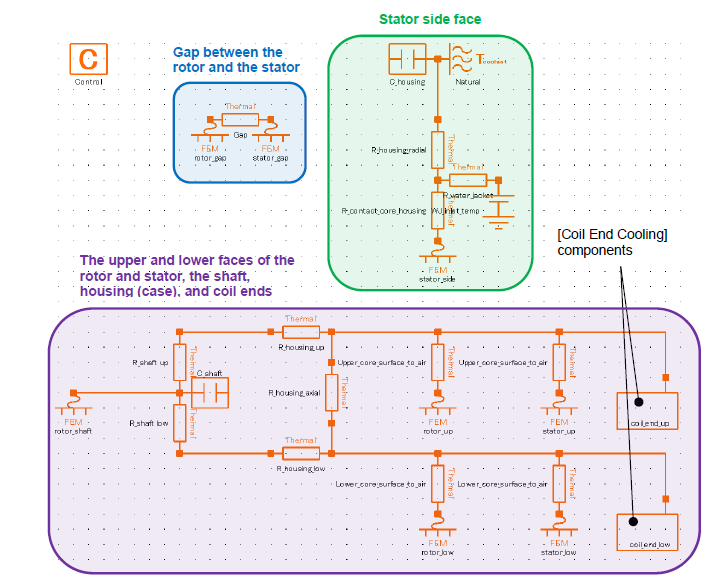

### 1 Part - FEM Gap (  1Gap(Resistor) + 2 FEM)

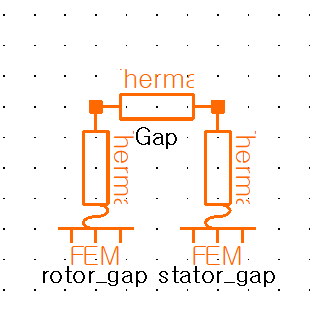

#### Thermal Resistor

로터와 고정자처럼 분리된 두 물체 사이에 열이 전달되는 경우 열 회로의 열 저항 부품을 사용합니다. 

두 물체 사이에 상당히 얇은 간격이나 코팅과 같은 단열재를 통해 열이 전달되는 경우 접촉 열 저항 조건을 사용합니다.

% Gap - Thermal Resistor - Cooling (Forced Convection )
% * scaleFactor

% 
Steady2.GetCircuit().GetComponent("Gap").SetValue("Characteristic Length", [num2str(stack_length),'*scaleFactor'])
Steady2.GetCircuit().GetComponent("Gap").SetValue("GapWidth", [num2str(gap_length),'*scaleFactor'])
Steady2.GetCircuit().GetComponent("Gap").SetValue("RotorRadius", [num2str(rotor_radius),'*scaleFactor'])
Steady2.GetCircuit().GetComponent("Gap").SetValue("ThermalResistorArea", "1*Area_Rotor_Gap_Face")
% Steady2.GetCircuit().GetComponent("Gap").SetValue("ThermalResistorArea", "1*Rotor_Gap_area")

Steady2.GetCircuit().GetComponent("Gap").SetValue("ThermalCorrection", "1*1")
Steady2.GetCircuit().GetComponent("Gap").SetValue("FlowVelocity", "1*74418.05")


### 2 Part - Housing (1 Cap+3 Resistor + 1 Convection + 1FEM)

General Contact

Cooling Water jacket

Thermal Conduction (Cylinder)

C_Housing

Natural & or Constant Resistance

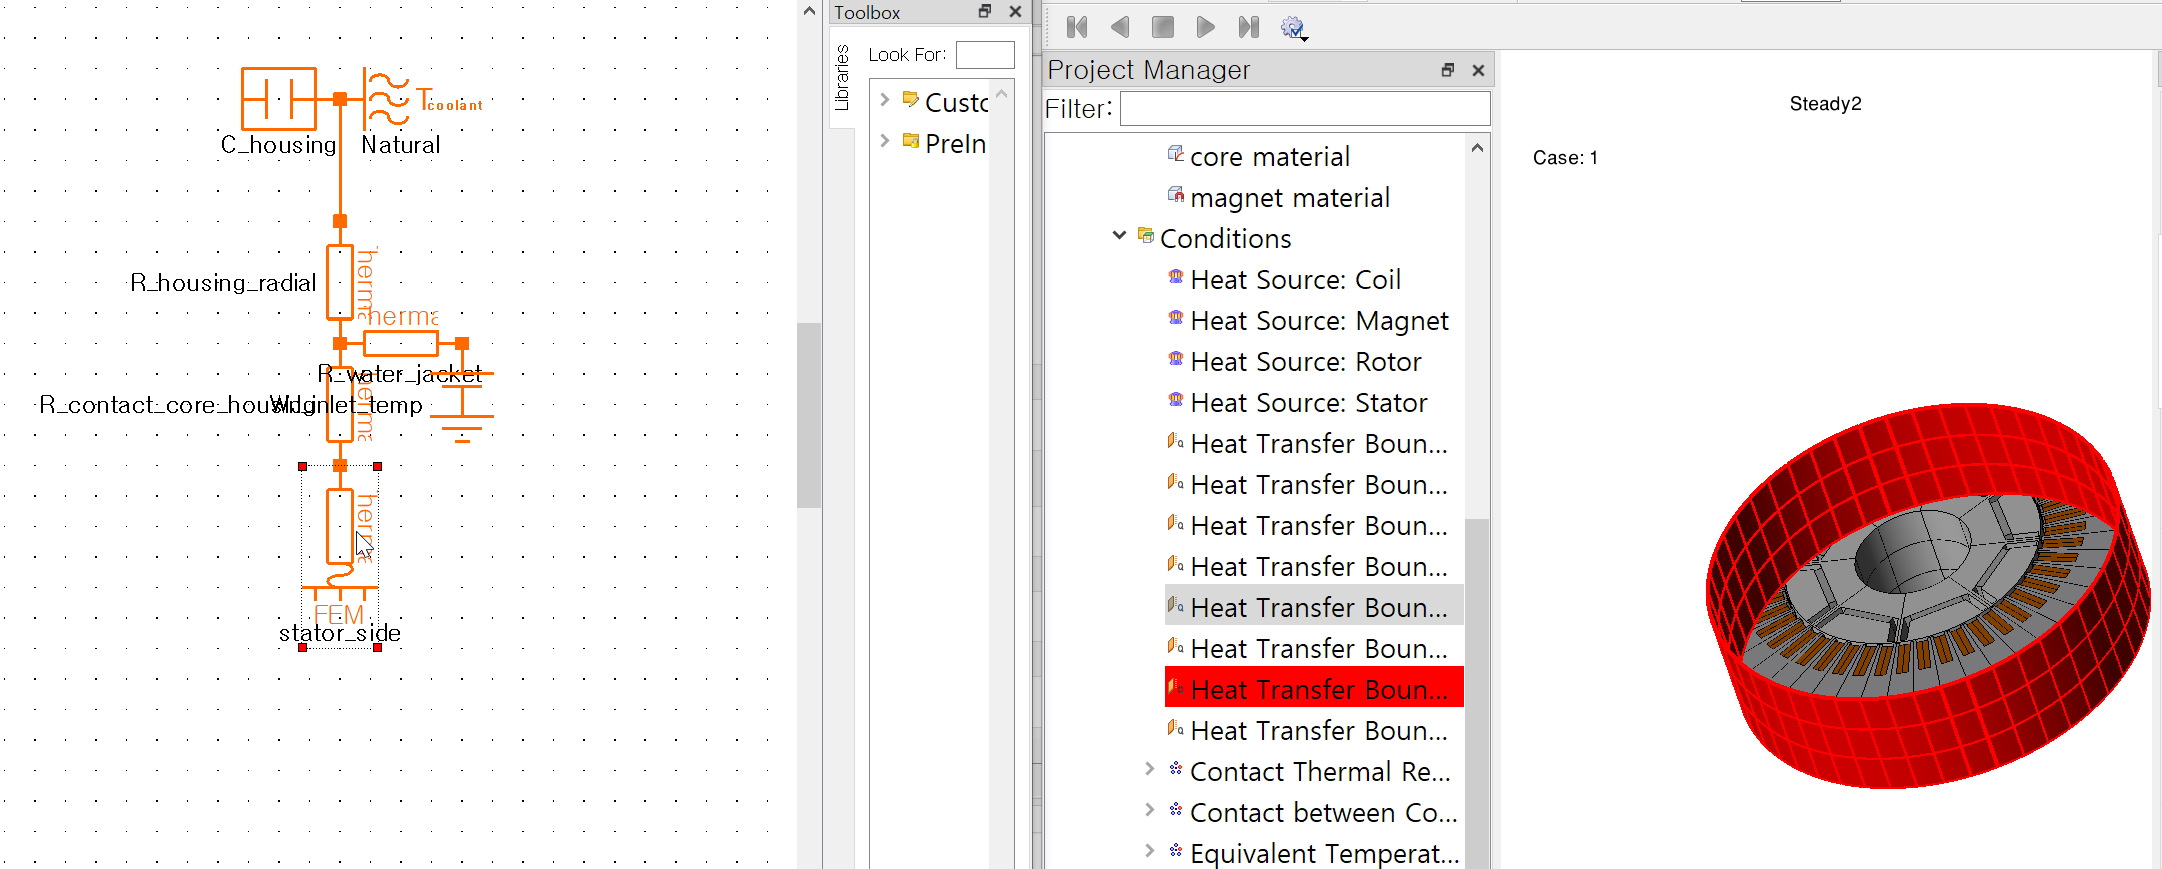

1.R_contact_core_housing 

Housing 과 접하는 Core 접촉저항 설정

#### Thermal Resistor (contact & conduction & Convection

% R_contact_core_housing 
% General Contact

% FEM은 circuit load에 따라 다르게

Steady2.GetCircuit().GetComponent("R_contact_core_housing").SetValue("ThermalConductivity", 0.02)
Steady2.GetCircuit().GetComponent("R_contact_core_housing").SetValue("ThermalCorrection", 4)
if contains(MachineData.runnerType,'inner','IgnoreCase',true)
    Steady2.GetCircuit().GetComponent("R_contact_core_housing").SetValue("ThermalResistorArea", "stator_side_area")
else
    Steady2.GetCircuit().GetComponent("R_contact_core_housing").SetValue("ThermalResistorArea", "Rotor_side_area")
end

% %% c.f calcRthGenContact (valid)
% fitType  = 0.01 % [mm]
% housing_Core_ThermalConductivity=0.02  %[mm^2]
% stator_side_area=2775;
% % 
% if contains(MachineData.runnerType,'inner','IgnoreCase',true)
%     side_area =stator_side_area
% else
%     side_area =Rotor_Core_Side_Face
% end
% RthHousingCore = calcRthGenContact(4, fitType, housing_Core_ThermalConductivity, side_area)  % degC/W

#### 7 Cooling Water jacket 

% 7 Cooling Water jacket 
Steady2.GetCircuit().GetComponent("R_water_jacket").SetValue("FlowVelocity",           num2str(WJ_velocity))
Steady2.GetCircuit().GetComponent("R_water_jacket").SetValue("RectangularTubeNumber", num2str(WJ_tube_number))
Steady2.GetCircuit().GetComponent("R_water_jacket").SetValue("RectangularTubeWidth",  [num2str(WJ_tube_width), '*scaleFactor'])
Steady2.GetCircuit().GetComponent("R_water_jacket").SetValue("RectangularTubeHeight", [num2str(WJ_tube_height),'*scaleFactor'])
Steady2.GetCircuit().GetComponent("R_water_jacket").SetValue("RectangularTubeRadius", [num2str(WJ_tube_radius),'*scaleFactor'])


% c.f RthWaterJacket
% HTC_water=14000
% RthWaterJacket = calcRthWaterJacket(4, HTC_water, WJ_tube_radius, WJ_tube_width, WJ_tube_number)

#### R_housing_radial

%  R_housing_radial
% Thermal Conduction (Cylinder)
% % 
% % % set Equation 
% addJMAGEqaution("Housing_height",[num2str(housing_height),'*scaleFactor'],Steady2)
% addJMAGEqaution("Housing_outer_radius",[num2str(Housing_outer_radius),'*scaleFactor'],Steady2)
% addJMAGEqaution("Housing_inner_radius",[num2str(Housing_inner_radius),'*scaleFactor'],Steady2)
% addJMAGEqaution("TC_housing",[num2str(housing_conductivity)],Steady2)

% set Thermal Resistor with  Thermal Conduction (Cylinder)
Steady2.GetCircuit().GetComponent("R_housing_radial").SetValue("ThermalConductivity", 25)   % W/m/degC
Steady2.GetCircuit().GetComponent("R_housing_radial").SetValue("ThermalResistorCylinderHeight", "Housing_height")
Steady2.GetCircuit().GetComponent("R_housing_radial").SetValue("ThermalResistorOuterRadius", "Housing_outer_radius")
Steady2.GetCircuit().GetComponent("R_housing_radial").SetValue("ThermalResistorInnerRadius", "Housing_inner_radius")
Steady2.GetCircuit().GetComponent("R_housing_radial").SetValue("ThermalCorrection", 1) % CF
% c.f Cylinder Resistance
% RthHousingRadial = calcRthRadial(1, housing_conductivity, housing_height*scaleFactor,  Housing_outer_radius*scaleFactor,Housing_inner_radius*scaleFactor)


#### Heat Capacity

- C Housing

#### 
$$$C=C_F \rho C_p V$$$



$$$C$ : Heat capacity $(\mathrm{J} / \mathrm{deg} C)$
$\rho:$ Density of the heat-radiating object $\left(\mathrm{g} / \mathrm{cm}^{\wedge} 3\right)$
$C_p$ : Specific heat of the heat-radiating object $(\mathrm{J} / \mathrm{kg} / \mathrm{deg} \mathrm{C})$
$V$ : Volume of the heat-radiating object $\left(\mathrm{mm}^{\wedge} 3\right)$
$C_F$ : Correction factor (Default: 1)$$


% C_Housing
housing_density              = 7800    
housing_specific_heat        = 450
V_housing = calcHousingVolume(housing_outer_diameter*scaleFactor, housing_inner_diameter*scaleFactor, housing_height*scaleFactor)
C_housing=calcHeatCapa(housing_density,housing_specific_heat,V_housing)
% C_Housing=12759.55*1/4
Steady2.GetCircuit().GetComponent("C_housing").SetValue("HeatCapacity", num2str(C_housing))



#### Convection Cooling

Natural & or Constant Resistance

% Natural & or Constant Resistance
Steady2.GetCircuit().GetComponent("Natural").SetValue("Thermal Area", "2*pi* Housing_outer_radius* Housing_height")
Steady2.GetCircuit().GetComponent("Natural").SetValue("CharacteristicLengthNatural", "Housing_outer_radius *2")

% c.f Constant Resistance
% HTC_air = 10;
% A_housing=calcCylinderArea(housing_height*scaleFactor,housing_outer_diameter*scaleFactor);
% R_housing_to_ambient = 1 / HTC_air / A_housing;



### 3. Part - ( 8 Resistor + 1 Cap + 7 FEM)

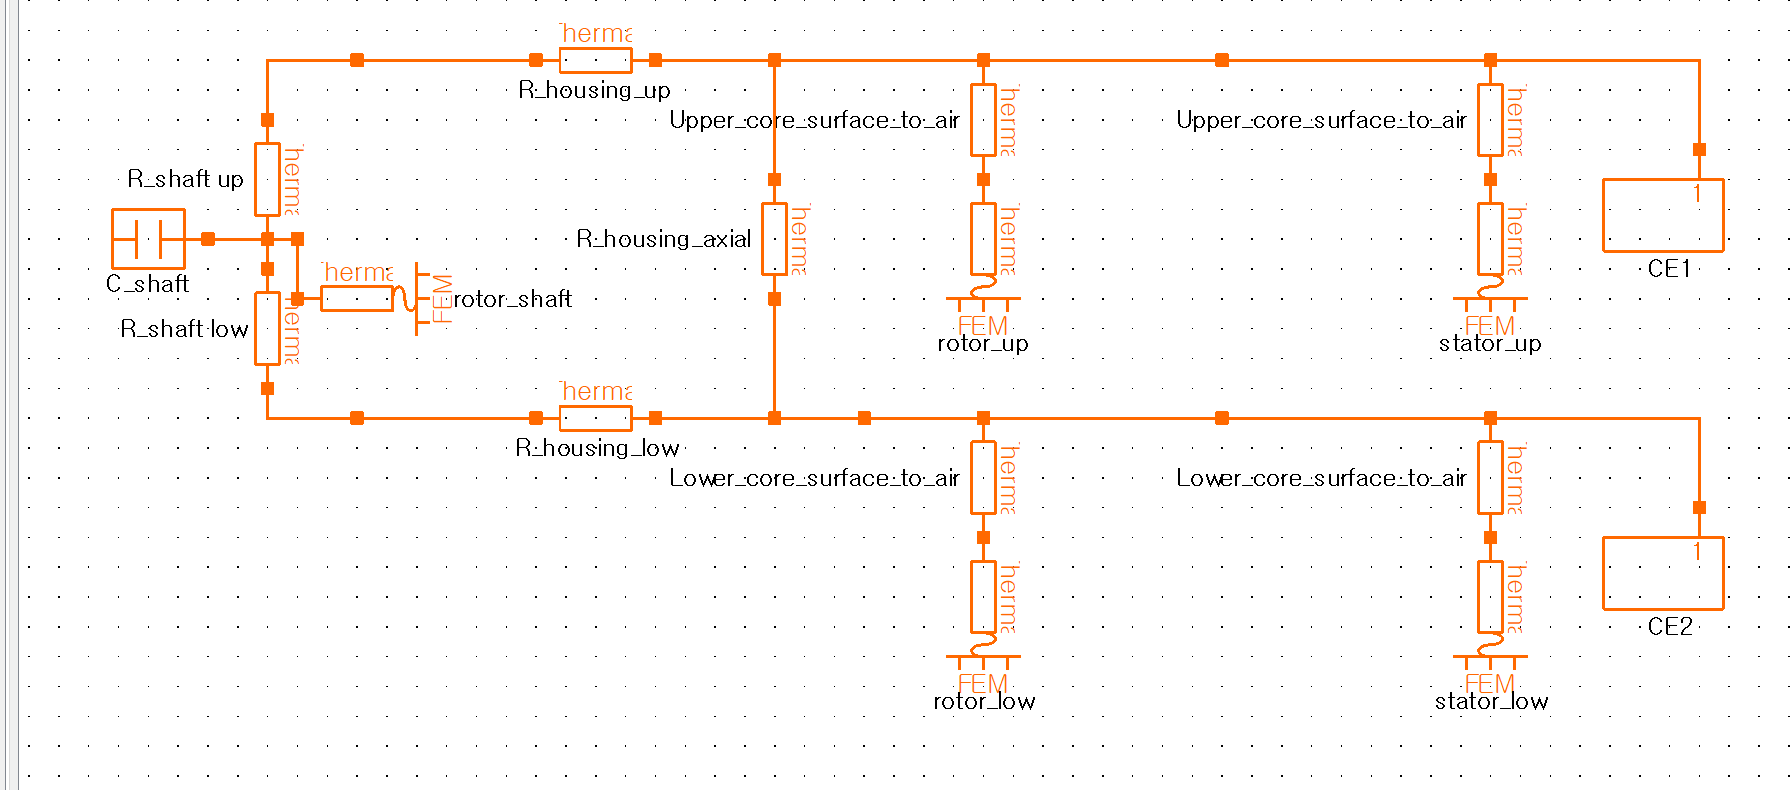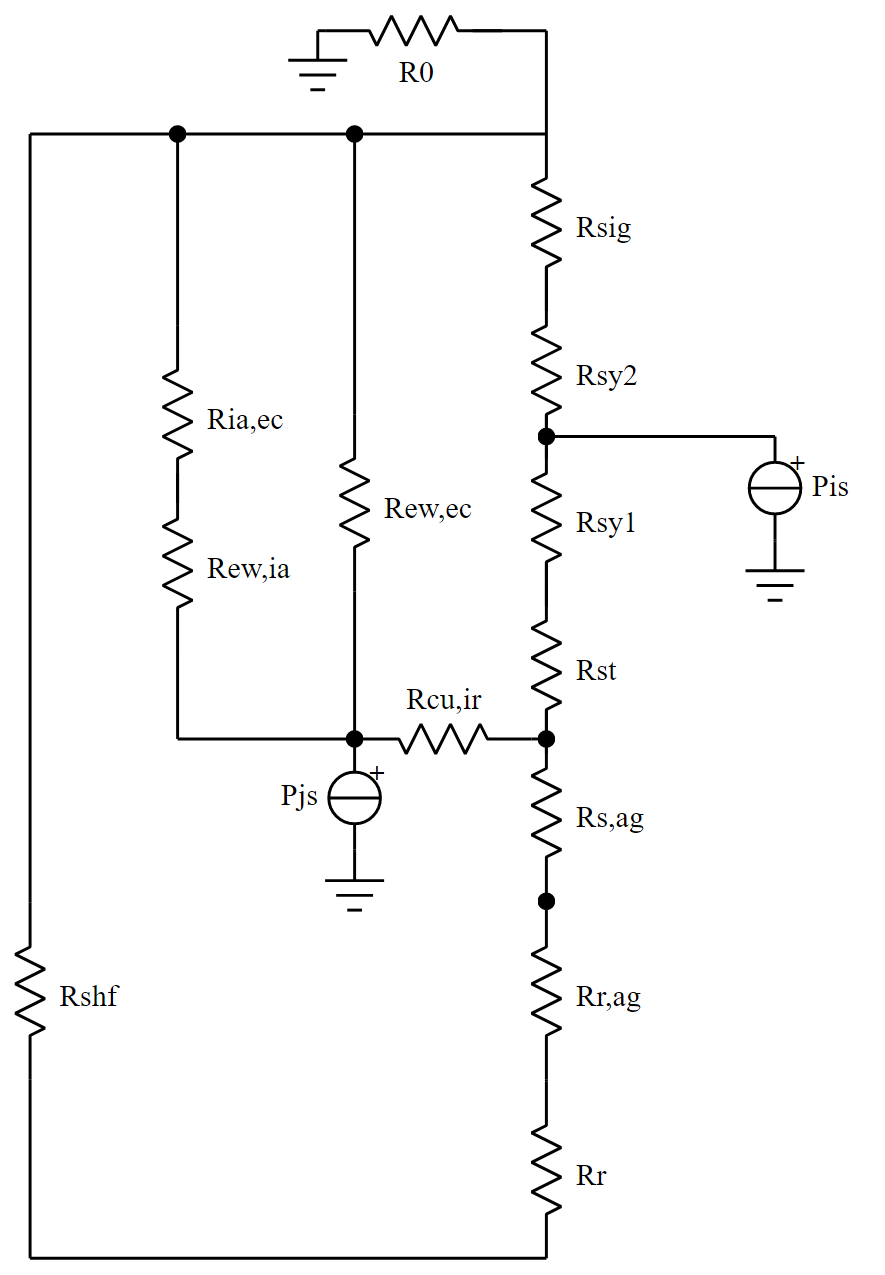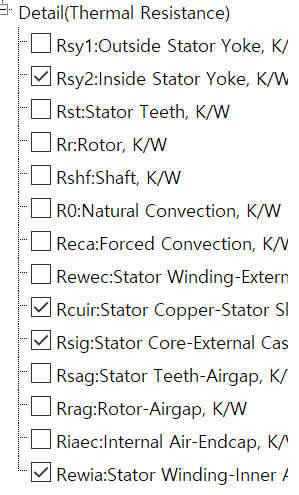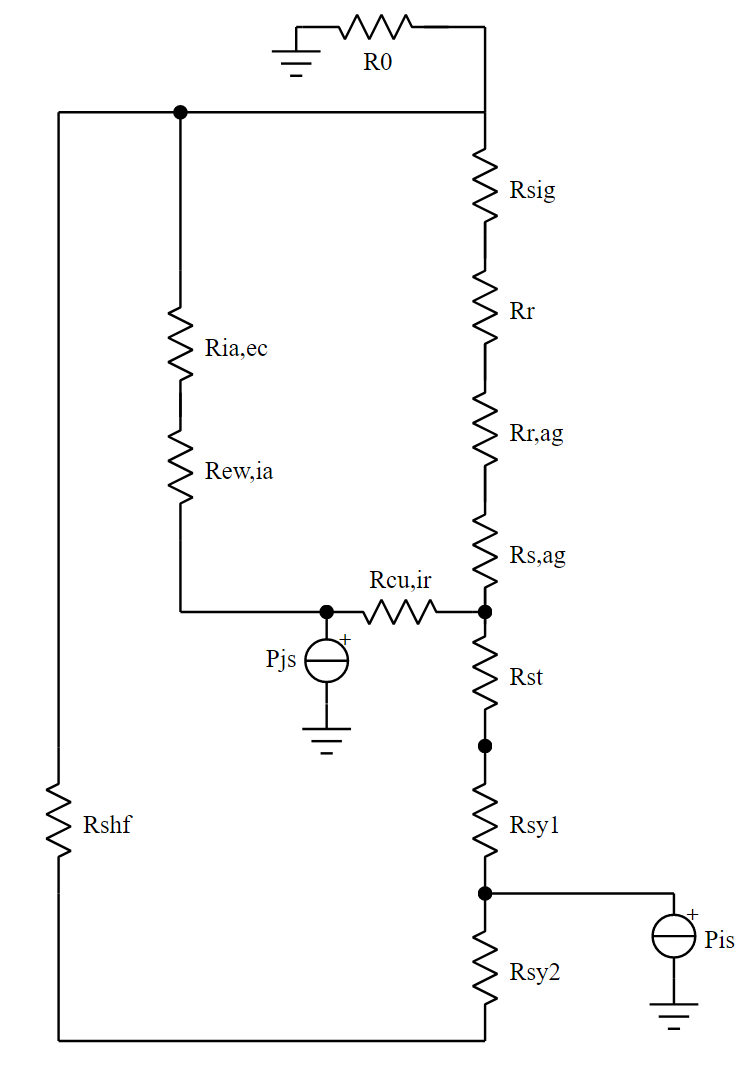

#### rotor Shaft

 FEM- rotor_shaft

R_shaft_up & low

C_shaft

%3 R_shaft up & % 13 R_shaft low
    % Constant Resistance
A_shaft=(pi * (shaft_diameter*scaleFactor / 2)^2 )
R_shaft = calcRthGenContact(1, shaft_length*scaleFactor, shaft_conductivity, A_shaft)
% R_shaft = (1 / shaft_conductivity) * (shaft_length / 1000) / (pi * (shaft_diameter / 2)^2 / 1000000)
R_shaft_up = R_shaft/2;
R_shaft_low = R_shaft/2;
Steady2.GetCircuit().GetComponent("R_shaft up").SetValue("ThermalResistor", num2str(R_shaft_up))
Steady2.GetCircuit().GetComponent("R_shaft_low").SetValue("ThermalResistor", num2str(R_shaft_low))

% C_shaft
V_shaft = (shaft_length*scaleFactor / 1000) * (pi * (shaft_diameter*scaleFactor / 2 / 1000)^2);
C_shaft=calcHeatCapa(shaft_density,shaft_specific_heat,V_shaft)
Steady2.GetCircuit().GetComponent("C_shaft").SetValue("HeatCapacity", num2str(C_shaft))


#### Housing

R_housing_up & low

R_housing_axial

 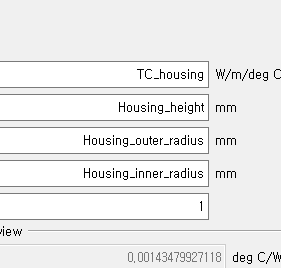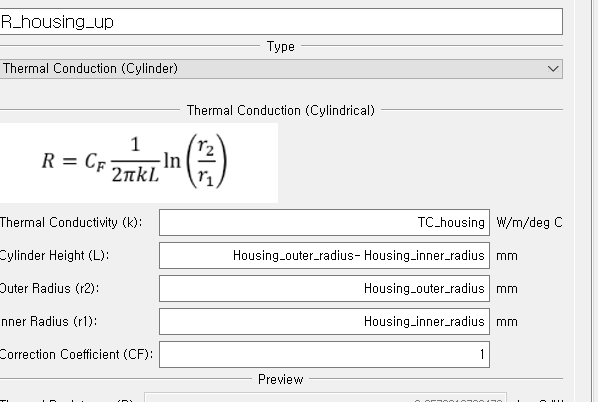


% 4 R_housing_up
    % Thermal Conduction (Cylinder)
Steady2.GetCircuit().GetComponent("R_housing_up").SetValue("ThermalResistorCylinderHeight", "Housing_outer_radius-Housing_inner_radius")
Steady2.GetCircuit().GetComponent("R_housing_up").SetValue("ThermalResistorOuterRadius", "Housing_outer_radius")
Steady2.GetCircuit().GetComponent("R_housing_up").SetValue("ThermalResistorInnerRadius", "Housing_inner_radius")
Steady2.GetCircuit().GetComponent("R_housing_up").SetValue("ThermalCorrection", 1)
% 14 R_housing low
    % Thermal Conduction (Cylinder)
Steady2.GetCircuit().GetComponent("R_housing_low").SetValue("ThermalResistorCylinderHeight", "Housing_outer_radius-Housing_inner_radius")
Steady2.GetCircuit().GetComponent("R_housing_low").SetValue("ThermalResistorOuterRadius", "Housing_outer_radius")
Steady2.GetCircuit().GetComponent("R_housing_low").SetValue("ThermalResistorInnerRadius", "Housing_inner_radius")
Steady2.GetCircuit().GetComponent("R_housing_low").SetValue("ThermalCorrection", 1)

% 5 R_housing_axial
    % Constant Resistance
% R_housing_axial = (1 / housing_conductivity) * (housing_height / 1000) / (pi * (housing_outer_diameter / 2 / 1000)^2 - pi * (housing_inner_diameter / 2 / 1000)^2);
% A_housing=calcCylinderSideArea(housing_height,housing_outer_diameter);
A_housingTop = calcCircleArea(housing_outer_diameter*scaleFactor, housing_inner_diameter*scaleFactor)
Resis_housing_axial = calcRthGenContact(1, housing_height*scaleFactor, housing_conductivity, A_housingTop)
Steady2.GetCircuit().GetComponent("R_housing_axial").SetValue("ThermalResistor", Resis_housing_axial)

% 위처럼 되는 이유 MarginNote 필기 그림 참조 Shaft-> Housing 

#### Core

Upper_core_surface_to_air

FEM rotor up

Lower_core_surface_to_air

FEM rotor low

Upper_core_surface_to_air

FEM stator up

Lower_core_surface_to_air

FEM stator low


% 6 Upper_core_surface_to_air
    % Constant Resistance
% RthST2AirUp=(1/HTC_air)/(core_stator_area*SLOTS*3/4/1000000)
% 9 Lower_core_surface_to_air
% RthST2AirLow=(1/HTC_air)/(core_stator_area*SLOTS*3/4/1000000)

% (1/HTC_air)/(core_stator_area/1000000)

% 11 Upper_core_surface_to_air
% RthRT2AirUp=(1/HTC_air)/(core_rotor_area*POLES/1000000)
% RthRT2AirLow=(1/HTC_air)/(core_rotor_area*POLES/1000000)
% 12 Lower_core_surface_to_air

% 10 R_coilend_to_air2
R_coilend_to_air2=Steady2.GetCircuit().GetInstance("R_coilend_to_air2",0)
R_coilend_to_air2.IsValid

% R_coilend_to_air2.MoveTo(-100,44)

#### Coil End Cooling

% Thermal Resistor
% coilend_surface_area     =           
% coilend_area             = 
% AddEquation
addJMAGEqaution("RthCoilEnd",[num2str((1/coilend_conductivity)),'/(coilend_area/1e6)*(CoilEndHeight*scaleFactor/1000)'],Steady2)
% RthCoilEnd=(1/coilend_conductivity)/(coilend_area/1e6)*(coilend_height*scaleFactor/1000)  % [degC/W]
% Heat Capacity
% CpCoilEnd=coilend_specific_heat*coilend_density*coilend_area/1e9             % [J/degC]
addJMAGEqaution("CpCoilEnd",[num2str(coilend_specific_heat*coilend_density),'*coilend_area/1e9'],Steady2)

addJMAGEqaution("Tcoolant",num2str(70),Steady2)
% Thermal Resistance
% RthConvCoilEnd=1/(HTC_air*coilend_surface_area/stack_length*scaleFactor*coilend_height*scaleFactor/1e6)   % [degC/W]
% addJMAGEqaution("RthConvCoilEnd",['1/(HTC_air*coilend_surface_area/stack_length*scaleFactor*CoilEndHeight*scaleFactor/1e6)'],Steady2)
addJMAGEqaution("RthConvCoilEnd",num2str(1),Steady2)

% Steady2.GetCircuit().GetComponent("CE1").SetValue("ThermalResistance", RthCoilEnd)
Steady2.GetCircuit().GetComponent("CE1").SetValue("ThermalResistance", "RthCoilEnd")

Steady2.GetCircuit().GetComponent("CE1").SetValue("HeatCapacity", 'CpCoilEnd')
Steady2.GetCircuit().GetComponent("CE1").SetValue("ThermalResistanceCooling1", 'RthConvCoilEnd')


Steady2.GetCircuit().GetComponent("CE2").SetValue("ThermalResistance", "RthCoilEnd")

Steady2.GetCircuit().GetComponent("CE2").SetValue("HeatCapacity", 'CpCoilEnd')
Steady2.GetCircuit().GetComponent("CE2").SetValue("ThermalResistanceCooling1", 'RthConvCoilEnd')

#### Thermal Area

% Steady2.GetCircuit().GetComponent("Natural").SetValue("Thermal Area", "2*pi*HEIGHT*scaleFactor*SD1*scaleFactor")


## 4. Setting Thermal Condition

Table -> 

JmagThermalConditionTable

ConditionPropertiesTable

Condition Type

Condition FaceTable

Condition Name

Condition Component

Condition Value Table

allocate SetList(GeomFace, Circuit Component, Condition Name)

### [TB] defJmagThermalConditionTable

JmagThermalConditionTable=defJmagThermalConditionTable(runnerType)
% 'HeatTransfer'
JmagThermalConditionTable.ConditionType(contains(JmagThermalConditionTable.GeomSetName,'Face'))='HeatTransfer'
% 'SameTemperatureBoundaryPattern'
JmagThermalConditionTable.ConditionType(contains(JmagThermalConditionTable.ConditionName,'End'))='SameTemperatureBoundaryPattern'
% ContactResistanceRotationPattern
JmagThermalConditionTable.ConditionType(contains(JmagThermalConditionTable.ConditionName,'Magnet'))='ContactResistanceRotationPattern'
% CustomContactResistanceRotationPattern
JmagThermalConditionTable.ConditionType(contains(JmagThermalConditionTable.ConditionName,'Coil-Core'))='CustomContactResistanceRotationPattern'

## [WIP]char2CategoricalPropertiesTable

% ParameterList  , inherits
% CurrentCondition.GetPropertyTable()
% conditionProperties=   ContactRConditionObj.GetPropertyTable()
% resultCategoricalTable = char2CategoricalPropertiesTable(conditionProperties)
% resultCategoricalTable.PropertiesName
% contains(resultCategoricalTable.PropertiesName,'')
% 
% SetList4AreaList
% AssemTable.GeomSetList

### Set Heat Transfer Boundary ( 8 ea)

get SetList 

allocate SetList(GeomFace, Circuit Component, Condition Name)

get SetList 

allocate SetList(GeomFace, Circuit Component, Condition Name)


for ConditionIndex=1:height(JmagThermalConditionTable)
    % 
    % if ~isempty(JmagThermalConditionTable.GeomSetName(ConditionIndex))
    %     JmagThermalConditionTable.ConditionType(ConditionIndex) ='HeatTransfer'
    % end
    
    ConditionType=cellstr(JmagThermalConditionTable.ConditionType(ConditionIndex))
    setFaceName=JmagThermalConditionTable.GeomSetName{ConditionIndex}
    CircuitComponentName=JmagThermalConditionTable.CircuitComponent{ConditionIndex}
    
    ConditionObj=Steady2.GetCondition(JmagThermalConditionTable.ConditionName{ConditionIndex});
    if (ConditionObj.IsValid)
        if strcmp(ConditionObj.GetType,'Heat Transfer Boundary') 
    % CurrentCondition=Steady2.CreateCondition("HeatTransfer", JmagThermalConditionTable.ConditionName(ConditionIndex))
        % setObj=Model3d.GetSetList().GetSet(setFaceName)
        % setObj.IsValid
        ConditionObj.AddSet(Model3d.GetSetList().GetSet(setFaceName), 0)
        % ConditionObj.AddSetFromModel(setFaceName, 0)
        ConditionObj.SetValue("RefTemperatureType", 1)
        ConditionObj.SetLink(CircuitComponentName)
        ConditionObj.SetValue("Coefficient", 10000)
        end
    else 
        if strcmp(ConditionType,'HeatTransfer')
        ConditionObj=Steady2.CreateCondition(ConditionType{:}, JmagThermalConditionTable.ConditionName{ConditionIndex});   
        ConditionObj.AddSet(Model3d.GetSetList().GetSet(setFaceName), 0)
        ConditionObj.SetValue("RefTemperatureType", 1)
        ConditionObj.SetLink(CircuitComponentName)
        ConditionObj.SetValue("Coefficient", 10000)
        end
    end
end

## Setting the Contact Thermal Resistance Pattern(Rotation) Condition

#### [TC]Setting the Contact Thermal Resistance Pattern(Rotation) Condition

SetList4AreaList
AssemTable.GeomSetList
% emptyConditionValueTableRows = cellfun('isempty', JmagThermalConditionTable.ConditionValueTable);

ConditionObj=Steady2.CreateCondition("ContactResistanceRotationPattern", "Magnet-Core")
ConditionObj=Steady2.GetCondition("Magnet-Core")
ConditionObj.IsValid
conditionProperties=ConditionObj.GetPropertyTable()
resultCategoricalTable = char2CategoricalPropertiesTable(conditionProperties)

matchingRows2Table = filterMCADTableWithAnyInfo(resultCategoricalTable, 'ThermalConductivity','PropertiesName')
matchingRows2Table.PropertiesValue{1}=0.02
% CurrentCondition=Steady2.CreateCondition(ConditionType{:}, JmagThermalConditionTable.ConditionName{ConditionIndex})

ConditionObj.SetValue("ThermalConductivity", 0.02)
ConditionObj.SetValue("Thickness", 0.01)
ConditionObj.SetValue("NumCopies", "POLES")
ConditionObj.ClearParts()
ConditionObj.AddSet(Model3d.GetSetList().GetSet("core_Magnet Face"), 0)


### [TC]Setting Coil and Core Contact Patter(Rotation) 

ConditionObj=Steady2.CreateCondition("CustomContactResistanceRotationPattern", "Coil-Core")
ConditionObj=Steady2.GetCondition("Coil-Core")
ConditionObj.IsValid
ConditionObj.GetName
% conditionProperties=ConditionObj.GetPropertyTable()
% resultCategoricalTable = char2CategoricalPropertiesTable(conditionProperties)
% matchingRows2Table = filterMCADTableWithAnyInfo(resultCategoricalTable, 'ThermalConductivity','PropertiesName')
% matchingRows2Table.PropertiesValue{1}=0.02
ConditionObj.SetValue("ContactType", int32(1))
ConditionObj.SetValue("InsulationThickness", 0.05)
ConditionObj.SetValue("Pressure", 0.21)
ConditionObj.SetValue("NumCopies", "SLOTS")
ConditionObj.ClearParts()
ConditionObj.AddSet(Model3d.GetSetList().GetSet("Coil-Stator Core Face"), 0)


### [TC]Setting the Equivalent Temperature Boundary Pattern

Steady2=Model3d.GetStudy(int32(0))
ConditionObj=Steady2.GetCondition("CoilEnd_low")
ConditionObj.IsValid
ConditionObj.GetName
ConditionObj.SetValue("NumCopies", "SLOTS")
ConditionObj.SetLink('CE2')

% [TB]
% JmagThermalConditionTable=setJmagCondition(JmagThermalConditionTable,Model3d,studyObj)



### Heat Source


% 
modelsel.SelectPart(GroupPartStruct.Magnet{1})
% for GroupIndex=1:NumGroups
% addJmagHeatSourceCondition(Model3d,Steady2,GroupNameList{GroupIndex},CellPartIds)
% end
% 
% ConditionObj=Steady2.GetCondition('Magnet')
% ConditionObj.GetPartsByGroup(0)
getSel=ConditionObj.GetSelection
% getSel.Add

addJmagHeatSourceCondition(Model3d,Steady2,'Conduc','Conductor_')
% CoilHeatObj.SetValue("ConstantAmount", "20*1000*1000*0.01")
ConducOjb=Steady2.GetCondition('Conduc')
DCLoss= 0.017*4378^2*3
DCLosskW=DCLoss/1000
ConducOjb.SetValue("ConstantAmount", num2str(DCLoss))

% addJmagHeatSourceCondition(Model3d,Steady2,'Rotor','Rotor Core')
ConducOjb=Steady2.GetCondition('RotorC')
RotorLoss=3100.37924727
RotorLosskW=RotorLoss/1000
RotorLossMW=RotorLosskW/1000

ConducOjb.SetValue("ConstantAmount", num2str(RotorLoss))

% addJmagHeatSourceCondition(Model3d,Steady2,'Stator','Stator Core')
ConducOjb=Steady2.GetCondition('Stator')
StatorLoss=49010.2824833
StatorLosskW=StatorLoss/1000
StatorLossMW=StatorLosskW/1000
ConducOjb.SetValue("ConstantAmount", num2str(StatorLoss))

addJmagHeatSourceCondition(Model3d,Steady2,'Magnet','Magnet')

ConducOjb=Steady2.GetCondition('Magnet')
MagLoss=13*40000
MagLosskW=MagLoss/1000
MagLossMW=MagLosskW/1000
MagLossDensity=MagLoss/(mm32m3(4207328537.40065)*350*3)
ConducOjb.SetValue("ConstantAmount", num2str(MagLoss))

TotalLoss=MagLoss+StatorLoss+RotorLoss+DCLoss
TotalLosskW=TotalLoss/1000
TotalLossMW=TotalLosskW/1000
% (20-TotalLossMW)/20*100
% 1541874.83466/1000/1000

### SetMaterial

GroupListObj=app.GetModel(1).GetGroupList();
Steady2=app.GetModel(1).GetStudy(0)
NumGroups=GroupListObj.NumGroups
for GroupIndex=1:NumGroups
    %% Get One Part From GropObj
    GroupObj=GroupListObj.GetGroup(GroupIndex-1);
    GroupObj.IsValid
    GroupName=GroupObj.GetName
    PartofGroupObj=GroupObj.GetPartByIndex(1);

    %% SetMaterialByName
    if contains(GroupName,'Conduc','IgnoreCase',true)
    Steady2.SetMaterialByName(PartofGroupObj.ID, "coil material")
    elseif contains(GroupName,'tor','IgnoreCase',true)
    Steady2.SetMaterialByName(PartofGroupObj.ID, "core material")
    elseif contains(GroupName,'mag','IgnoreCase',true)
    Steady2.SetMaterialByName(PartofGroupObj.ID, "magnet material")
    end

end

Model3d=app.GetModel(1)

ModelSel=Model3d.CreateSelection()
ModelSel.SelectPart(PartofGroupObj.ID)
app.GetModel(u"PMSG_350P_300S_v1_case1Thermal_10").GetStudy(u"ThermalStudy1").SetMaterialByName(u"Conduc", u"coil material")

